# Конвертация цветовых пространств

Помимо RGB, cуществуют и другие цветовые пространства, например, HSV – Hue, Saturation, Value – тон, насыщенность, значение (яркость)

Чтобы преобразовать изображение из одного цветового пространства в другое, используются функции:

`rgb2hsv`

`hsv2rgb`

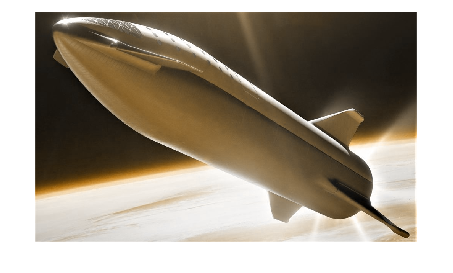

A = imread("BFS_rocket.jpg");
original_image = A;
A = rgb2hsv(A);
A(:,:,1) = 0.1;
A = hsv2rgb(A);
imshow(A)

Также полезна функция перевода в оттенки серого `rgb2gray`:

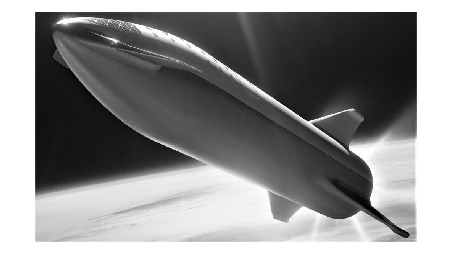

B = rgb2gray(original_image);
imshow(B)

Изображение в оттенках серого можно перевести в бинарное функцией `imbinarize`:

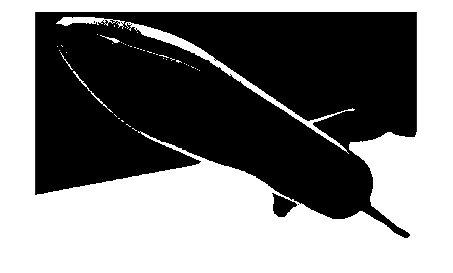

C = imbinarize(B);
imshow(C)

В MATLAB бинарное изображение имеет тип данных `logical`. Бинарные изображения содержат только 0 (False) и 1 (True). Пиксели со значением 0 отображены как черные; пиксели со значением 1 отображены как белые.